## **1. Denoising and Filtering**

(a) The input files are given as “speech.wav” and “noise.wav”. You should use function **audioread **to read the time-domain signal and the sampling frequency Fs. 

clear;clf;
[s,Fs] = audioread("speech.wav");
[n,~] = audioread("noise.wav");

(b) Add noise to the speech signal. Plot the original speech signal and noised speech signal in time domain as a waveform and frequency domain as its amplitude spectrum respectively.

Hint: The x-axis of the time domain waveform should be in seconds (s), which means that you need to calculate the corresponding time of each sampling point on the timeline first. For the frequency domain, you should give the amplitude as the y-axis and concrete frequency (Hz) from 0 to Fs/2 as the x-axis. You can use function fft() and abs() to get the N-point DFT of the signal.

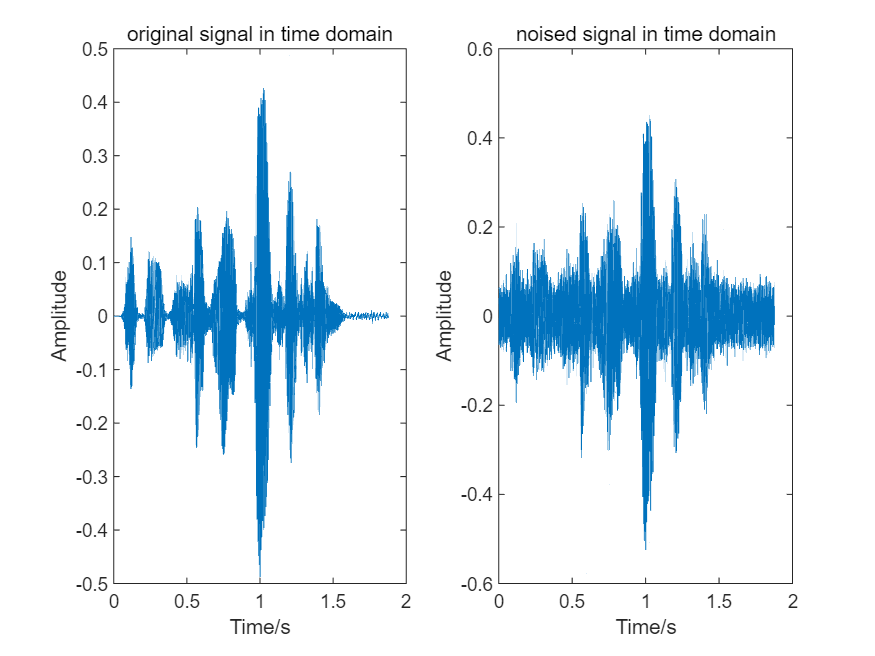

sn = s + n;
ffts = fft(s);
fftsn = fft(sn);
N = length(s);
t = (0:N-1)/Fs;
f = Fs/N*(0:round(N/2)-1);
figure;
subplot(1,2,1);plot(t,s);
title("original signal in time domain");xlabel('Time/s');ylabel('Amplitude');
subplot(1,2,2);plot(t,sn);
title("noised signal in time domain");xlabel('Time/s');ylabel('Amplitude');

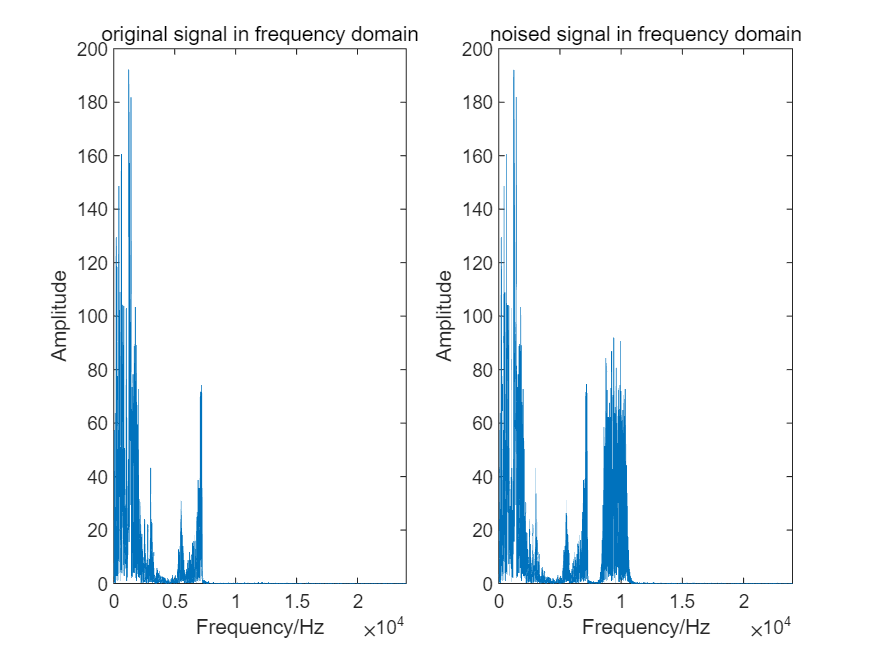

figure;
subplot(1,2,1);plot(f,abs(ffts(1:round(N/2))));
title("original signal in frequency domain");xlabel('Frequency/Hz');ylabel('Amplitude');
subplot(1,2,2);plot(f,abs(fftsn(1:round(N/2))));
title("noised signal in frequency domain");xlabel('Frequency/Hz');ylabel('Amplitude');

(c) The sound will be reflected back when it encounters an object in the transmission, and the auditory effect is like the echo of your shout in the valley. It is not difficult to understand that it is caused by the mixture of the original signal and the reflected signal. Therefore, the model of echo mixing can be expressed as follows:


$$y\left(t\right)=x\left(t\right)+\alpha *x\left(t-T_0 \right)$$



$$y\left(n\right)=x\left(n\right)+\alpha *x\left(n-N_0 \right)$$
                                  

Try to add echo to the noised speech signal from b). The echo is added after 1s, and the attenuation coefficient of the echo is 0.2 ($T_0 =1,\;\alpha =0\ldotp 2,\;N_0 =T_0 *F_s$). Plot the noised speech signal with echo in time domain as a waveform and frequency domain as its amplitude spectrum respectively.

Hint: You can add zeros before the start of the signal to get the echo. At the same time, the length of the signal will change by adding echo.

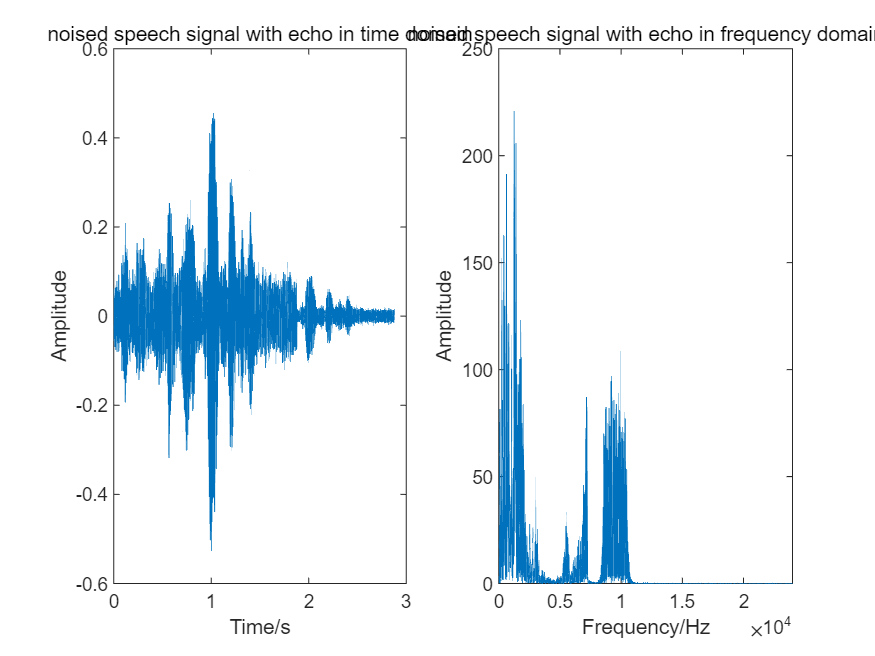

sn1 = [sn;zeros(1*Fs,1)];
sn2 = [zeros(1*Fs,1);0.2*sn];
sne = sn1 + sn2;
fftsne = fft(sne);
Ne = length(sne);
te = (0:Ne-1)/Fs;
fe = Fs/Ne*(0:round(Ne/2)-1);
figure;
subplot(1,2,1);plot(te,sne);
title("noised speech signal with echo in time domain");xlabel('Time/s');ylabel('Amplitude');
subplot(1,2,2);plot(fe,abs(fftsne(1:round(Ne/2))));
title("noised speech signal with echo in frequency domain");xlabel('Frequency/Hz');ylabel('Amplitude');

(d) Remove the echo by inverse filtering. The Z-transform converts a discrete-time signal into a complex frequency-domain. 


$$y\left(n\right)=x\left(n\right)+\alpha *x\left(n-N_0 \right)$$



$$y\left(n\right)\iff Y\left(z\right)\;\;\;\;$$

$$x\left(n\right)\iff X\left(z\right)$$



$$Y\left(z\right)=\left(1+\alpha *z^{-N_0 } \right)X\left(z\right)=H\left(z\right)X\left(z\right)$$



$$\;\;\;\;H\left(z\right)=1+\alpha *z^{-N_0 }$$


Therefore, echo mixing can be regarded as the generation of signal  after passing through $H\left(z\right)$. Then removing the echo can be realized by inverse filtering, and the inverse system of $H\left(z\right)$ is


$$H^{-1} \left(z\right)=\frac{1}{1+\alpha *z^{-N_0 } }$$


You can use function **filter **to implement inverse filtering as follow:

$b=\left\lbrack 1\right\rbrack ;a=\left\lbrack 1,\textrm{zeros}\left(1,N_0 -1\right),\alpha \right\rbrack$;


$$x=\textrm{filter}\left(b,a,y\right);$$


Try to implement inverse filtering to the noised speech signal with echo from c) to remove the echo. Plot the signal before and after the inverse filtering in time domain as a waveform respectively. 

Hint: You can use function** sound** to play the speech signal to verify whether the elimination of echo is successful

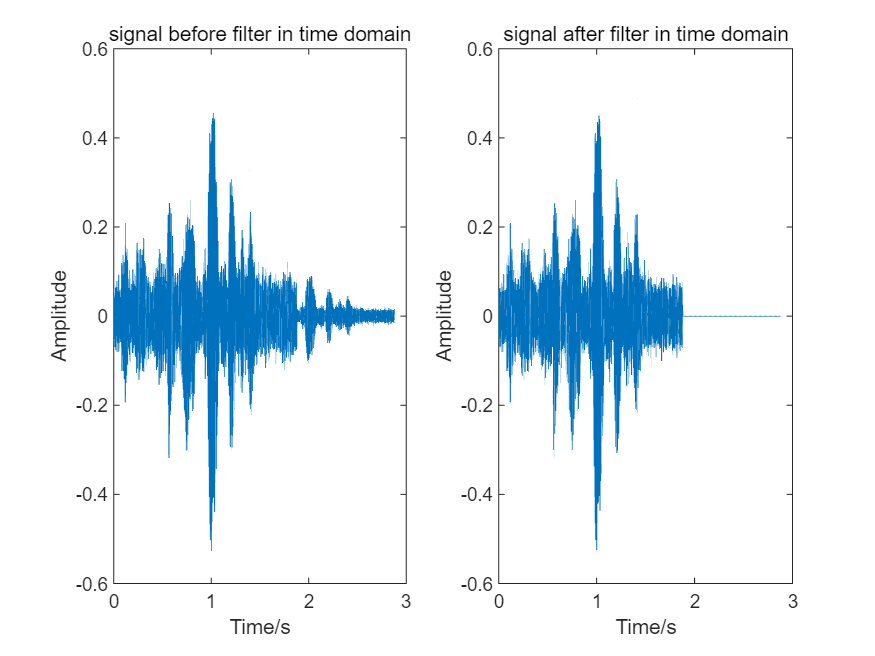

b = 1;
a = [1,zeros(1,1*Fs-1),0.2];
sn3 = filter(b,a,sne);
figure;
subplot(1,2,1);plot(te,sne);
title("signal before filter in time domain");xlabel('Time/s');ylabel('Amplitude');
subplot(1,2,2);plot(te,sn3);
title("signal after filter in time domain");xlabel('Time/s');ylabel('Amplitude');

(e) Design a FIR filter use **fdatool** command and filter the noised speech signal without echo from d) with function filter to remove the noise. You are required to declare the filter type you used and briefly explain the design parameters you choose. You are then required to plot: (1) The magnitude response of the filter in frequency domain; (2) The noised speech signal without echo from d) and the filtered signal in time domain as a waveform and frequency domain as its amplitude spectrum respectively.

Hint: You can also use function **sound** to play the speech signal to verify whether the elimination of noise is successful

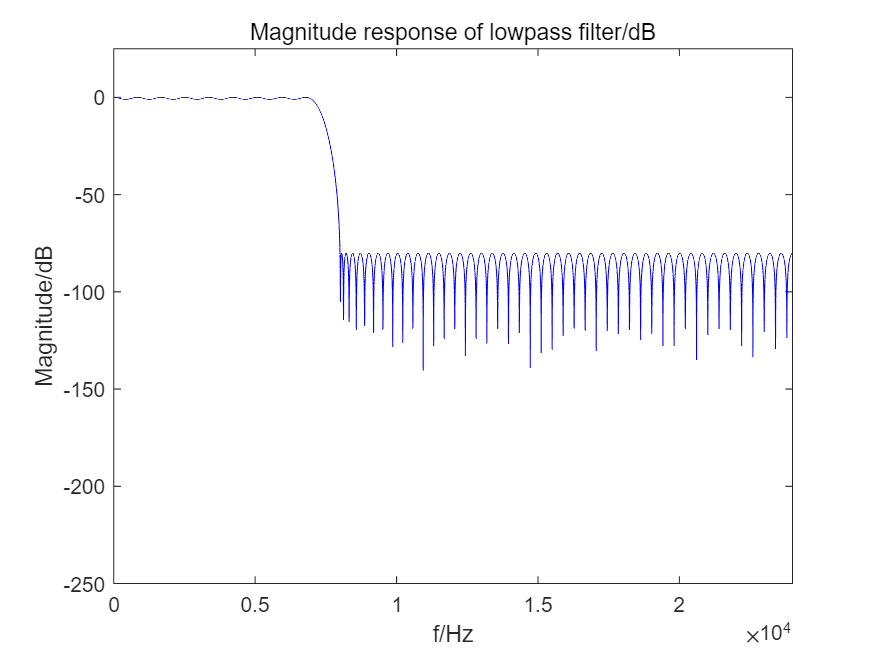

% declare the filter type you used and briefly explain the design parameters you choose 
% Lowpass FIR filter. The design paramaters, primarily Fpass and Fstop, are
% read from 1(b) by comparing original and noised signal in frequency domain
Hd = lowpass_filter;
[H,w]=freqz(Hd); 
dbH=20*log10(abs(H)/max(abs(H))); 
figure;
plot(w*Fs/(2*pi), dbH,'b'); 
axis([0 Fs/2 -250 25]);
title('Magnitude response of lowpass filter/dB');
xlabel('f/Hz');ylabel('Magnitude/dB');

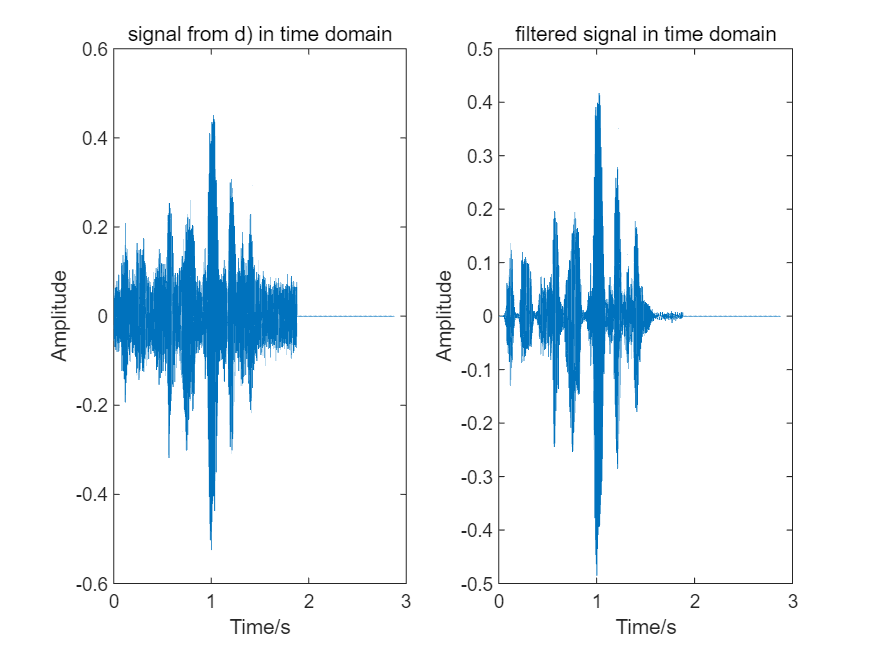

s1 = filter(Hd,sn3);
fftsn3 = fft(sn3);
ffts1 = fft(s1);
figure;
subplot(1,2,1);plot(te,sn3);
title("signal from d) in time domain");xlabel('Time/s');ylabel('Amplitude');
subplot(1,2,2);plot(te,s1);
title("filtered signal in time domain");xlabel('Time/s');ylabel('Amplitude');

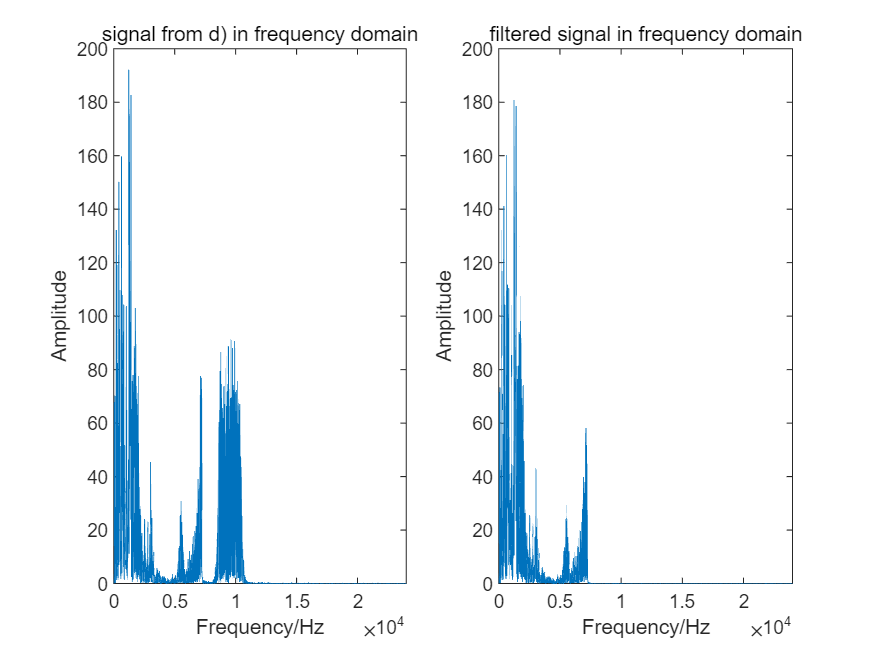

figure;
subplot(1,2,1);plot(fe,abs(fftsn3(1:round(Ne/2))));
title("signal from d) in frequency domain");xlabel('Frequency/Hz');ylabel('Amplitude');
subplot(1,2,2);plot(fe,abs(ffts1(1:round(Ne/2))));
title("filtered signal in frequency domain");xlabel('Frequency/Hz');ylabel('Amplitude');

## 2. **Audio Signal Processing **

(a)The input file is given as “handel.wav”. You should use function **audioread **to read the time-domain signal and the sampling frequency Fs. 

clear;clf;
[han,Fsh] = audioread("handel.wav");

(b)Plot the signal in time domain as a waveform and frequency domain as its amplitude spectrum. The x-axis of the time domain waveform should be in seconds (s). For the frequency domain, you should give the amplitude as the y-axis and concrete frequency (Hz) from 0 to Fs/2 as the x-axis. You can first use function **fft() **and** abs()** to get the N-point DFT of the signal.

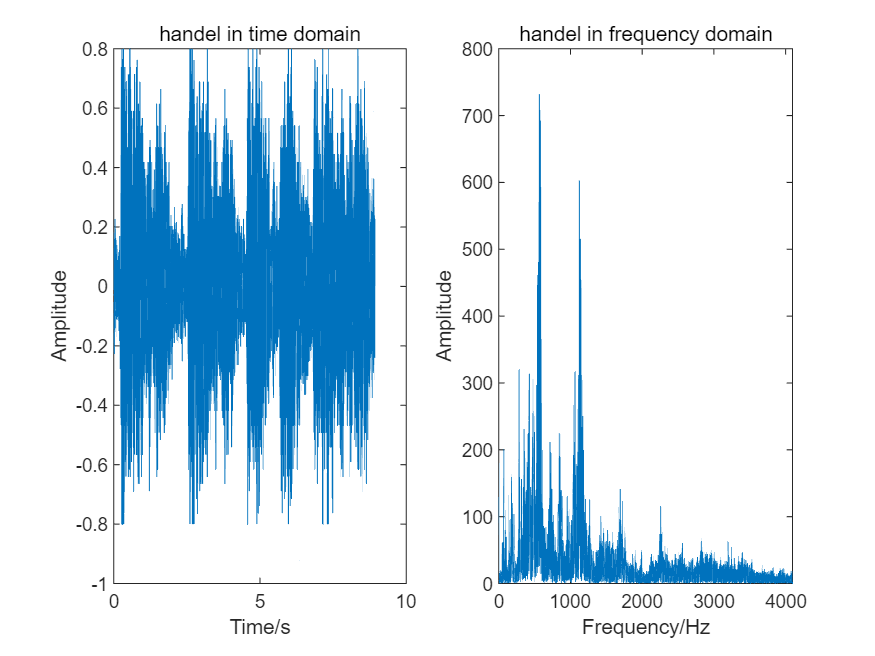

ffthan = fft(han);
Nh= length(han);
th = (0:Nh-1)/Fsh;
fh = Fsh/Nh*(0:round(Nh/2)-1);
figure;
subplot(1,2,1);plot(th,han);
title("handel in time domain");xlabel('Time/s');ylabel('Amplitude');
subplot(1,2,2);plot(fh,abs(ffthan(1:round(Nh/2))));
title("handel in frequency domain");xlabel('Frequency/Hz');ylabel('Amplitude');

(c)Make a simple equalizer. The equalizer allocates different weights various different frequency bandwidth. This can be realized by a couple of band-pass filters. In this case, eight filters are adopted for 32, 64, 125, 250, 500, 1k, 2k and 4kHz. Design the filters as you prefer and splice the signals filtered by your filters. Before filtering, consider the following questions. What is the filter type you choose? Is it time-domain or frequency domain? Is it IIR or FIR filter? What is the reason that you choose it? After that, Plot the spectrum of the difference of the original signal and filtered signal. (The difference should be minimized as far as possible, which is your task.)

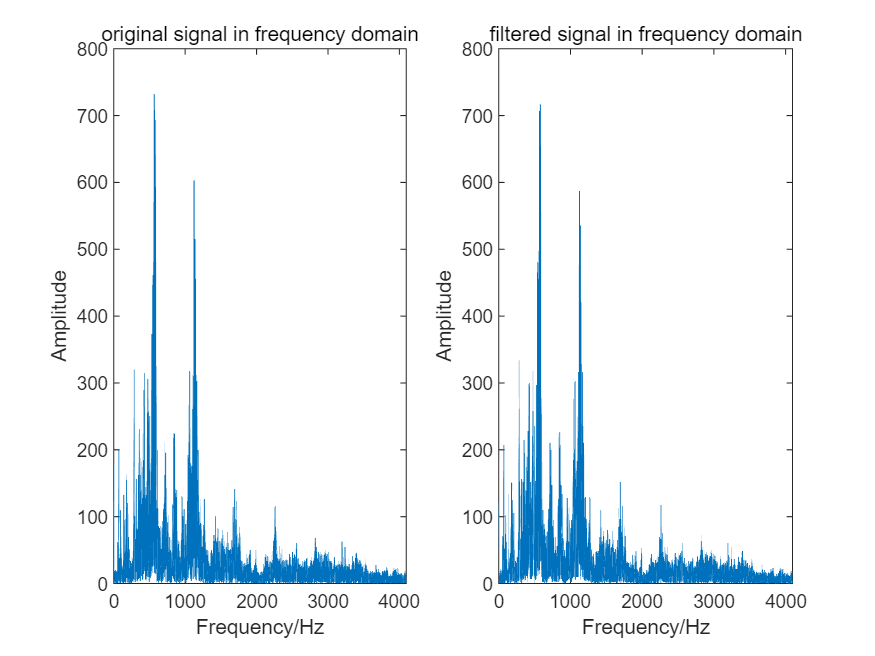

Hd1 = filter_32Hz;
Hd2 = filter_64Hz;
Hd3 = filter_125Hz;
Hd4 = filter_250Hz;
Hd5 = filter_500Hz;
Hd6 = filter_1kHz;
Hd7 = filter_2kHz;
Hd8 = filter_4kHz;
han1 = filter(Hd1,han);
han2 = filter(Hd2,han);
han3 = filter(Hd3,han);
han4 = filter(Hd4,han);
han5 = filter(Hd5,han);
han6 = filter(Hd6,han);
han7 = filter(Hd7,han);
han8 = filter(Hd8,han);
han9 = han1 + han2 + han3 + han4 + han5 + han6 + han7 + han8;
ffthan9 = fft(han9);
figure;
subplot(1,2,1);plot(fh,abs(ffthan(1:round(Nh/2))));
title("original signal in frequency domain");xlabel('Frequency/Hz');ylabel('Amplitude');
subplot(1,2,2);plot(fh,abs(ffthan9(1:round(Nh/2))));
title("filtered signal in frequency domain");xlabel('Frequency/Hz');ylabel('Amplitude');

(d)Assign weights for each filter to make the voice of human clearer. The values of weights can range from -12dB to 12dB. Plot the spectrum of the filtered signals again and save it through function **audiowrite**. 

Hint: dB is a parameter describing gain. $G\left(w\right)=20\log_{10} \left(\left|H\left(e^{\textrm{jw}} \right)\right|\right)$

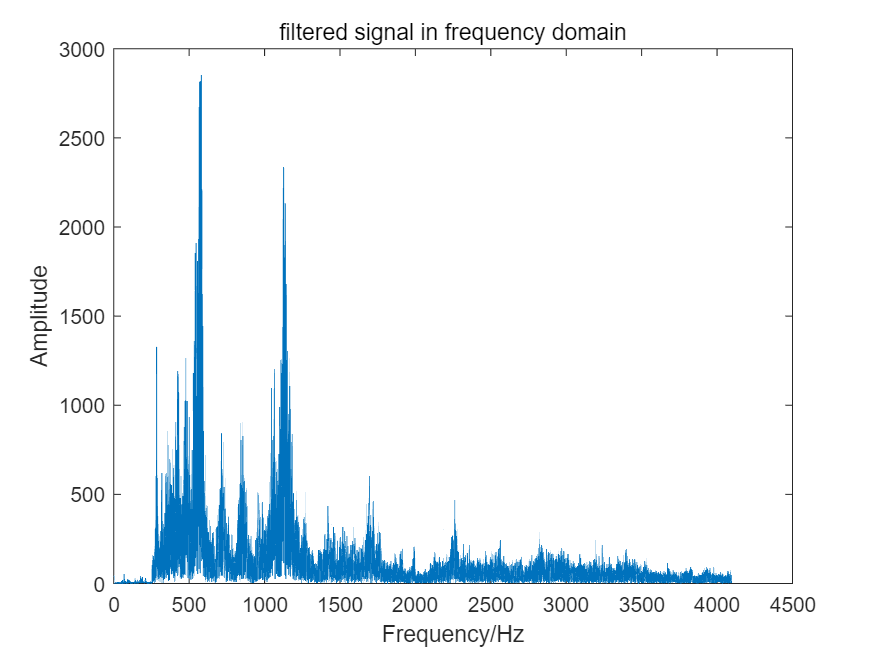

han10 = 10^(-0.6)*han1 + 10^(-0.6)*han2 + 10^(-0.6)*han3 + 10^(-0.6)*han4 + 10^(0.6)*han5 + 10^(0.6)*han6 + 10^(0.6)*han7 + 10^(0.6)*han8;
ffthan10 = fft(han10);
audiowrite("Handel_weight_filter.wav",rescale(han10,-1,1),Fsh);
figure;
plot(fh,abs(ffthan10(1:round(Nh/2))));
title("filtered signal in frequency domain");xlabel('Frequency/Hz');ylabel('Amplitude');

(e)Implement the voice transferring (voice to the opposite gender). Use function **resample **to try it. However, there may be two problems. When we upsample the audio, we need to drop out weak signals. When we downsample the audio, we need to padding to maintain the length of the audio. Plot the time-domain sequence and Fourier spectrum before and after the voice transferring. 

han11 = resample(han,7000,Fsh);
han11 = stretchAudio(han11,7000/Fsh);
han12 = resample(han,9000,Fsh);
han12 = stretchAudio(han12,9000/Fsh);
ffthan11 = fft(han11);
Nh11= length(han11);
th11 = (0:Nh11-1)/Fsh;
fh11 = Fsh/Nh11*(0:round(Nh11/2)-1);
ffthan12 = fft(han12);
Nh12= length(han12);
th12 = (0:Nh12-1)/Fsh;
fh12 = Fsh/Nh12*(0:round(Nh12/2)-1);
figure;
subplot(1,2,1);plot(th,han);
title("handel in time domain");xlabel('Time/s');ylabel('Amplitude');
subplot(1,2,2);plot(fh,abs(ffthan(1:round(Nh/2))));
title("handel in frequency domain");xlabel('Frequency/Hz');ylabel('Amplitude');

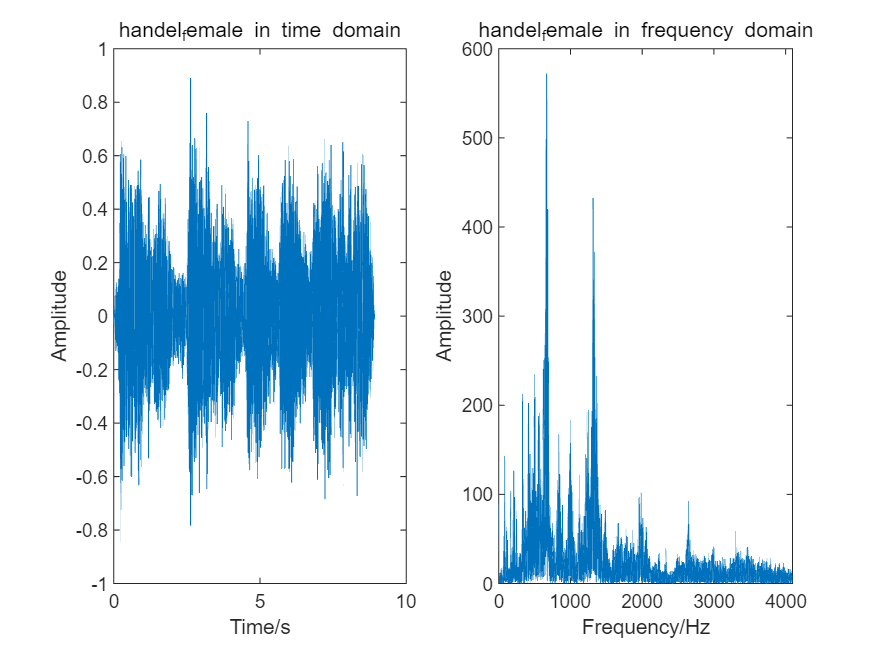

figure;
subplot(1,2,1);plot(th11,han11);
title("handel_female in time domain");xlabel('Time/s');ylabel('Amplitude');
subplot(1,2,2);plot(fh11,abs(ffthan11(1:round(Nh11/2))));
title("handel_female in frequency domain");xlabel('Frequency/Hz');ylabel('Amplitude');

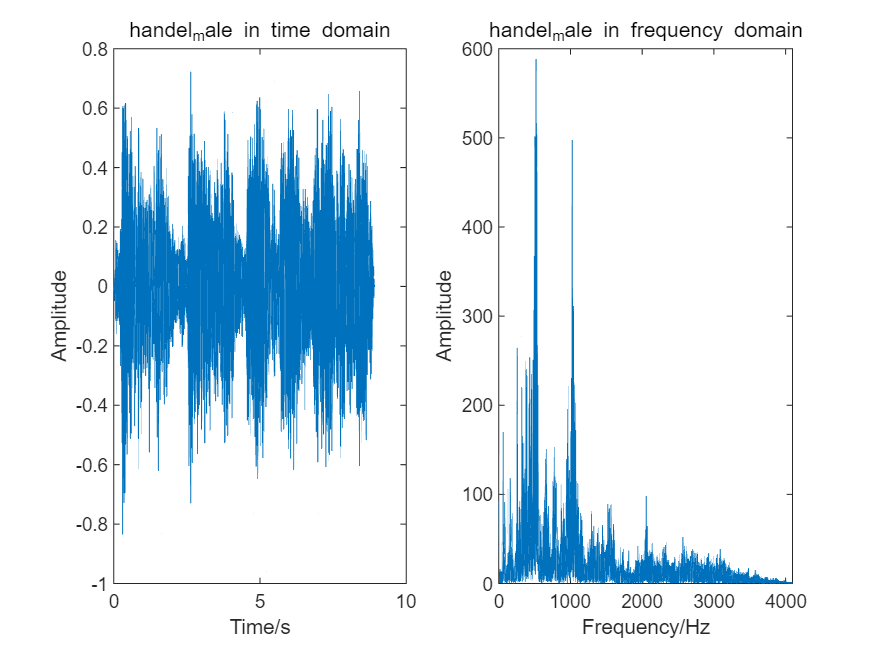

figure;
subplot(1,2,1);plot(th12,han12);
title("handel_male in time domain");xlabel('Time/s');ylabel('Amplitude');
subplot(1,2,2);plot(fh12,abs(ffthan12(1:round(Nh12/2))));
title("handel_male in frequency domain");xlabel('Frequency/Hz');ylabel('Amplitude');